clear;
img = imread("IMG_9528.JPG");


[height, width, ~] = size(img);

boxSize = 100;

% Number of full boxes
numOfBoxesHeight = floor(height / boxSize)

numOfBoxesHeight = 40

numOfBoxesWidth = floor(width / boxSize)

numOfBoxesWidth = 22


% Remainder after division
remHeight = mod(width, boxSize)

remHeight = 68

remWidth = mod(height, boxSize)

remWidth = 32

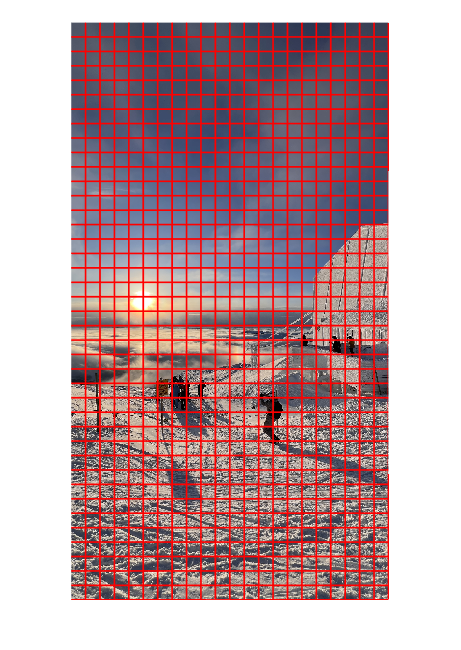


% Crop image, only keep full boxes

croppedImg = img(1:numOfBoxesHeight*boxSize, 1:numOfBoxesWidth*boxSize,:);

figure;
imshow(croppedImg)

hold on;

% Draw the grid lines
for i = 1:numOfBoxesWidth
    x = i * boxSize;
    line([x, x], [0, numOfBoxesHeight * boxSize], 'Color', 'r', 'LineWidth', 1);
end

for j = 1:numOfBoxesHeight
    y = j * boxSize;
    line([0, numOfBoxesWidth * boxSize], [y, y], 'Color', 'r', 'LineWidth', 1);
end

hold off;